%POLICY SEARCH NORMAL
clc;clear all;close all;
%step(GCL,40);hold on
z0=rand(12,1)% ---> fila de 1 x (nx*nu)

z0 =     0.7094
    0.7547
    0.2760
    0.6797
    0.6551
    0.1626
    0.1190
    0.4984
    0.9597
    0.3404


syms x [4 1]
syms u [3 1]
syms t

A=jacobian(pend(t,x,u),x);
B=jacobian(pend(t,x,u),u);

xd=[zeros(4,1)]; % --> zeros(nx,1)
ud=[zeros(3,1)]; %---> zeros(nu,1)

A=double(subs(A,[x;u],[xd;ud]))

A =      0     1     0     0
     0     1     0     0
     1     0     1     1
     0     0     0     1


B=double(subs(B,[x;u],[xd;ud]))

B =      0     0     0
     1     1     0
     0     0     1
     2    -1     0



Solver stopped prematurely.

fmincon stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 3.000000e+03.



zopt = 1.0e+03 *

    1.0666
    1.4730
    1.0531
    0.6197
    0.8565
    0.6064
   -0.3626
   -0.4929
   -0.2840
   -1.3154


Jopt = 9.6473

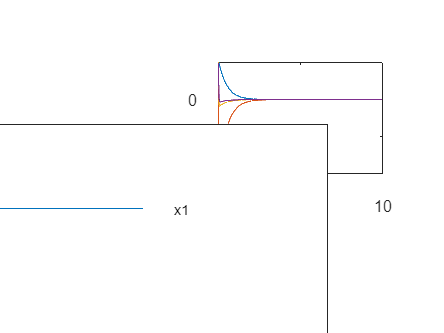



for i=4:4
    [zopt,Jopt]=fmincon(@(z)costo(z,i),z0,[],[],[],[],[],[],@(z)restr(z,A,B))
    x0=[0.5;0.5;0.5;0.5]; % ---> modificar X0
    [T,X]=ode45(@(t,x)pend(t,x,control(t,x,zopt)),[0 10],x0); % -->[t0 tn]
    plot(T,X(:,1));hold on;
    plot(T,X(:,2));
    plot(T,X(:,3));
    plot(T,X(:,4));
    legend('x1','x2','x3')
end

function J=costo(z,i)
    fun=@(t,x)pend(t,x,control(t,x,z));
    Ts=0.01;
    T=(0:Ts:4)';
    xk=[0.5;0.5;0.5;0.5];  % ---> X0
    Y=[];
    U=[];
    for k=1:length(T);
        U=[U;control(k*Ts,xk,z)];
        k1=fun(k*Ts,xk);
        k2=fun(k*Ts+Ts/2,xk+k1*Ts/2);
        k3=fun(k*Ts+Ts/2,xk+k2*Ts/2);
        k4=fun(k*Ts+Ts,xk+k3*Ts);
        xk=xk+Ts*(k1+2*k2+2*k3+k4)/6;
        Y=[Y,eye(4)*xk];%----> modificar las salidas
    end
    Yref=[0;0;0;0]; %----> modificar referencia
    if(i==1)
        J=sum(abs(Y-Yref))+0.01*sum((U.^2));
    elseif(i==2)
        J=sum(abs(Y-Yref).*T)+0.01*sum((U.^2));
    elseif(i==3)
        J=sum((Y-Yref).^2)+0.01*sum((U.^2));
    elseif(i==4)
        J=sum(sum((Y-Yref).^2)'.*T)+0.01*sum((U.^2));
    end
end

function [c,c_eq]=restr(z,A,B)
    K=reshape(z,[3 4]);% ---> modificar [nu nx]
    c=[max(real(eig(A-B*K)))+0.2];%% +2
    c_eq=[];
end
function u=control(t,x,z)
    K=reshape(z,[3 4]);% ---> modificar [nu nx]
    u=-K*x;
end

function dx=pend(t,x,u)
    dx=[x(2);
        u(1)+u(2)+sin(x(2));
        x(3)+x(4)+u(3)+sin(x(1))
        x(4)+2*u(1)-u(2)];
end
